# Pronóstico de Precios del Petróleo Crudo Utilizando Descomposición Wavelet Basada en Eliminación de Ruido con Modelo ARMA

% Cargar y Filtrar Datos

% Cargar datos desde un archivo CSV
data = readtable('MCEI.csv');

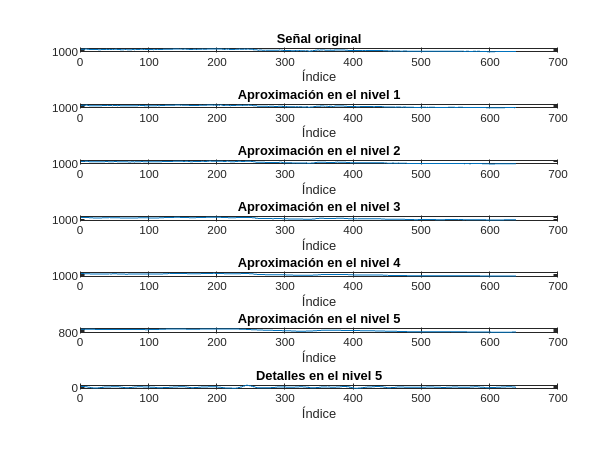

prices = str2double(data.Price); 
dates = datetime(data.Date, 'InputFormat', 'dd-MM-yyyy'); 

% Filtrar el intervalo de tiempo deseado
start_date = datetime('01-Jan-2019', 'InputFormat', 'dd-MMM-yyyy');
end_date = datetime('30-Jul-2021', 'InputFormat', 'dd-MMM-yyyy');
date_filter = (dates >= start_date) & (dates <= end_date);

% Aplicar filtro a precios y fechas
price = prices(date_filter);
date = dates(date_filter);

% Descomposición Wavelet y Visualización

% Define el número de niveles
niveles = 5;

% Aplica la descomposición wavelet
[C,L] = wavedec(price, niveles, 'sym4');

% Inicializa la figura
figure;

% Grafica la señal original
subplot(niveles+2, 1, 1);
plot(price);
title('Señal original');
xlabel('Índice');
ylabel('Precio');

% Grafica la aproximación en cada nivel
for i = 1:niveles
    subplot(niveles+2, 1, i+1);
    approx = wrcoef('a', C, L, 'sym4', i);
    plot(approx);
    title(['Aproximación en el nivel ' num2str(i)]);
    xlabel('Índice');
    ylabel('Aprox');
end

% Grafica los detalles en el último nivel
subplot(niveles+2, 1, niveles+2);
details = wrcoef('d', C, L, 'sym4', niveles);
plot(details);
title(['Detalles en el nivel ' num2str(niveles)]);
xlabel('Índice');
ylabel('Detalle');

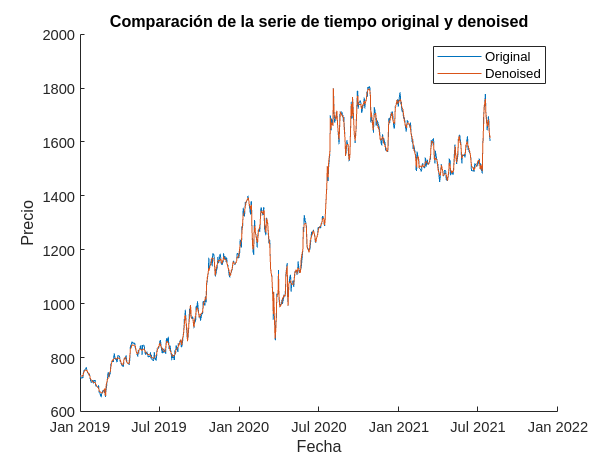


% Aplicar Denoising y ARIMA

% Aplicar la denoising usando wdenoise
x = wdenoise(price);

% Graficar la serie de tiempo original y la serie de tiempo denoised en el mismo plot
figure;
hold on;
plot(date, price);
plot(date, x);
hold off;

% Añadir leyenda y título
legend('Original', 'Denoised');
title('Comparación de la serie de tiempo original y denoised');
xlabel('Fecha');
ylabel('Precio');


% Ajustar modelo ARIMA para la serie original
model_original = arima('Constant',0,'D',1,'Seasonality',0);
fit_original = estimate(model_original, price);

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                Value     StandardError    TStatistic      PValue   
                ______    _____________    __________    ___________

    Constant         0            0             NaN              NaN
    Variance    1086.2       31.704          34.259      3.1652e-257



res_original = infer(fit_original, price);

% Ajustar modelo ARIMA para la serie denoised
fit_denoised = estimate(model_original, x);

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                Value     StandardError    TStatistic    PValue
                ______    _____________    __________    ______

    Constant         0            0             NaN       NaN  
    Variance    634.81       13.317          47.668         0  



res_denoised = infer(fit_denoised, x);

% Calcular RMSE y MAD
rmse_original = sqrt(mean(res_original.^2));
rmse_denoised = sqrt(mean(res_denoised.^2));
mad_original = mean(abs(res_original));
mad_denoised = mean(abs(res_denoised));

% Mostrar RMSE y MAD
disp(['RMSE Original: ' num2str(rmse_original)]);

RMSE Original: 32.9334


disp(['RMSE Denoised: ' num2str(rmse_denoised)]);

RMSE Denoised: 25.1938


disp(['MAD Original: ' num2str(mad_original)]);

MAD Original: 22.1978


disp(['MAD Denoised: ' num2str(mad_denoised)]);

MAD Denoised: 15.132
